## Naïve Bayes Analysis part 2

Analysis & Hyperparameter Search on the dataset here uses the standardised dataset with fewer features. 

Naive Bayes classification is performed using boostrapping, which is recomended for large datasets: the training and testing times are shortest..

Several metrics are calculated for the multiclass naive Bayes classifier: 

- precision, recall, accuracy[1] 

- F1 [2]. 

Training and testing of the training dataset is performed using MATlab's fitcnb and predict functionality [3]. All the kernel smoothing algorithms covered in the MATlab documentation [3] are evaluated.

### This section clears the workspace, loads the dataset

The dataset used is the standardised dataset, the features previously identified as not useful are removed.

% CLear all, load the dataset
clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
letterDataset.removeColumn("xBox");
letterDataset.removeColumn("yBox");
letterDataset.removeColumn("width");
letterDataset.removeColumn("height");
%[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
%X = table2array(X);
%Y = table2array(Y);
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
            isStandardised: 1
          isRemovedFeature: 1



## Run Hyperparameter Search

Find start of error range

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalNormalQuickHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesKernalNormalQuickSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 787.0000

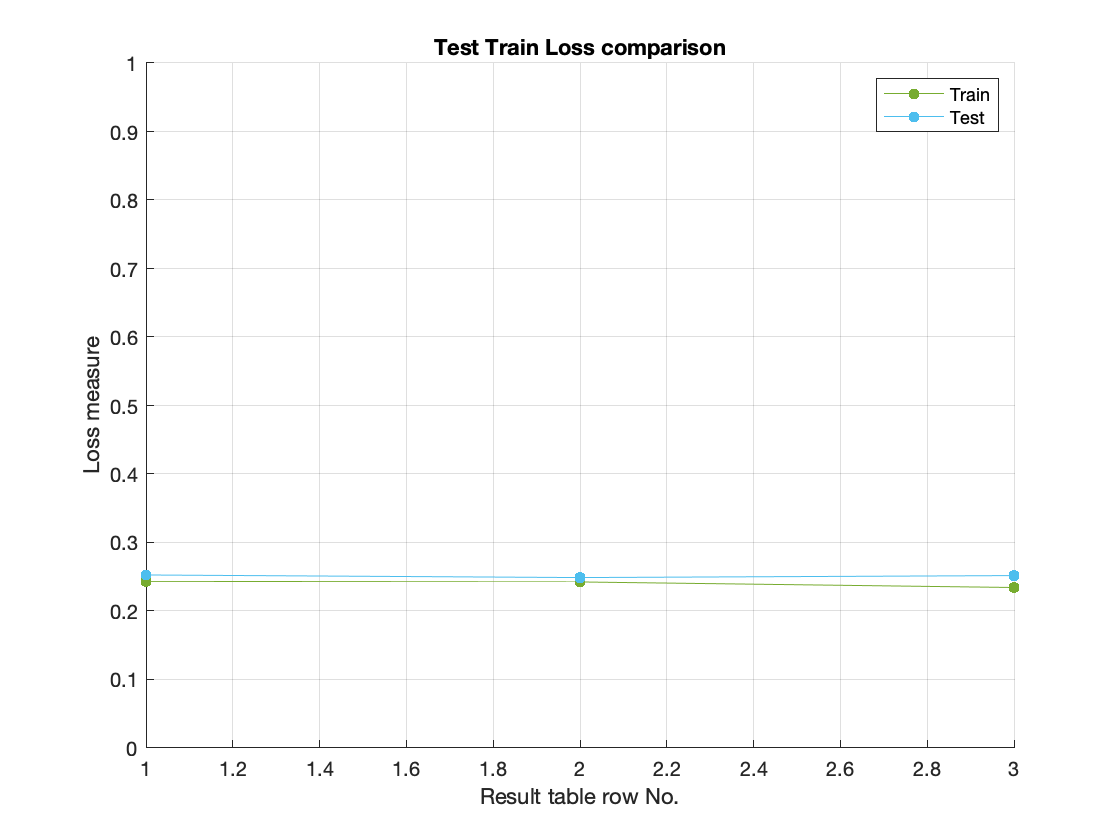

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

disp(results.resultsTable);

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}        {'normal'}      0.2           2                 2               0.24

### Using Default 'normal' Distribution Name

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getDefaultTestHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesDefaultSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 12.8500

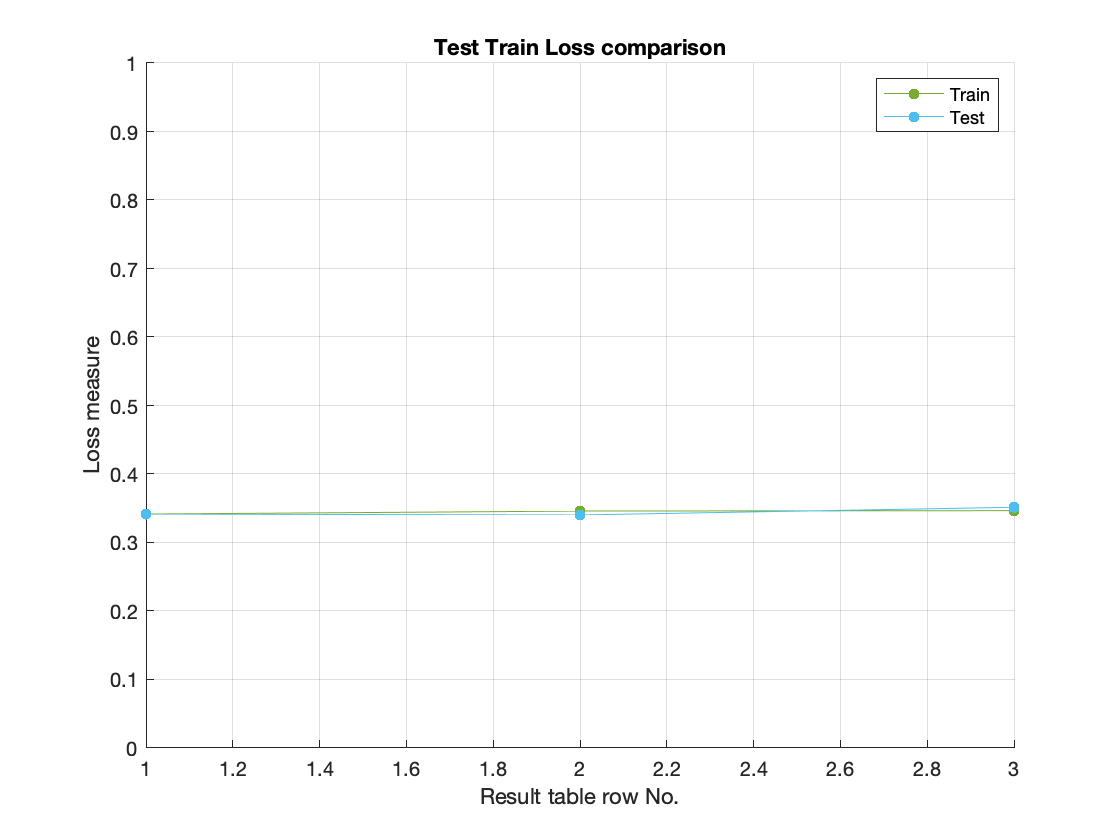

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

disp(results.resultsTable);

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'normal'}        {'unused'}      -1            2                 2               0.34

### Kernel Distribution Names (uses normal distribution for each feature)

#### Triangle Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernelTriangleSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesTriangleSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 3904.2800

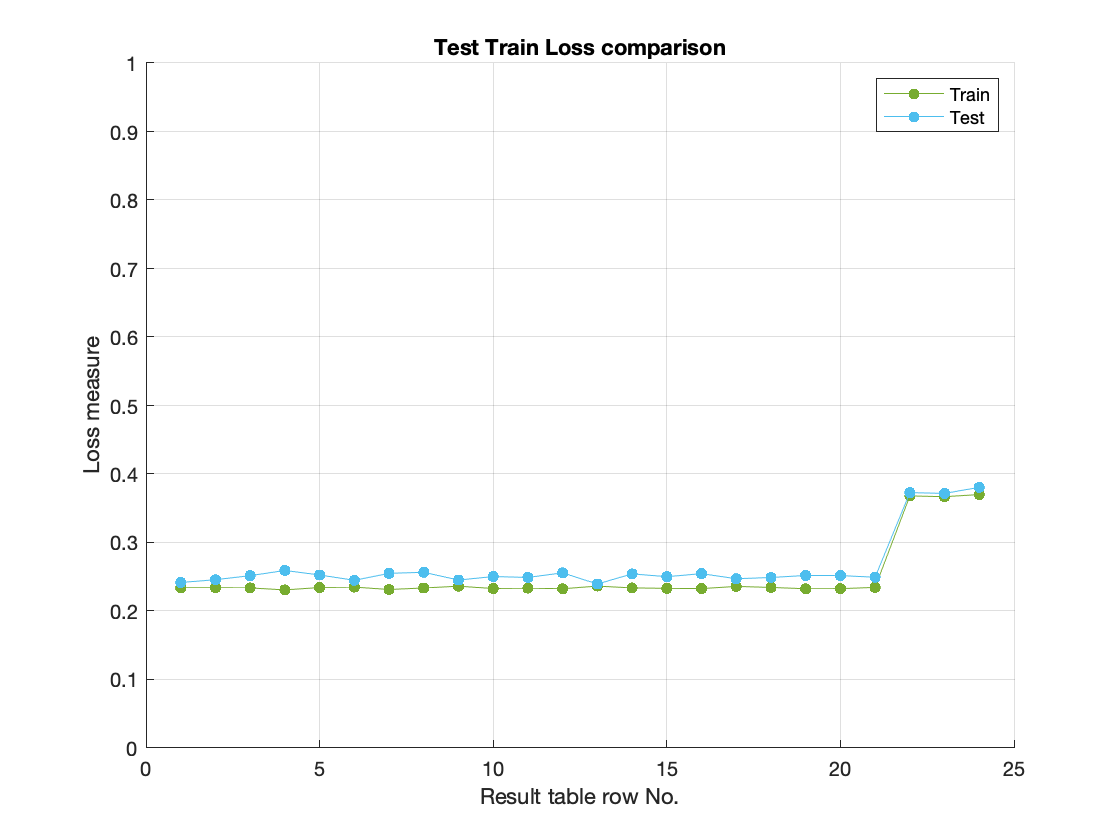

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

disp(results.resultsTable);

    distributionName    smootherType     Width      numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    ________    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'}        0.13          2                 2          

#### Normal Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalNormalSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesNormalSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 6626.0400

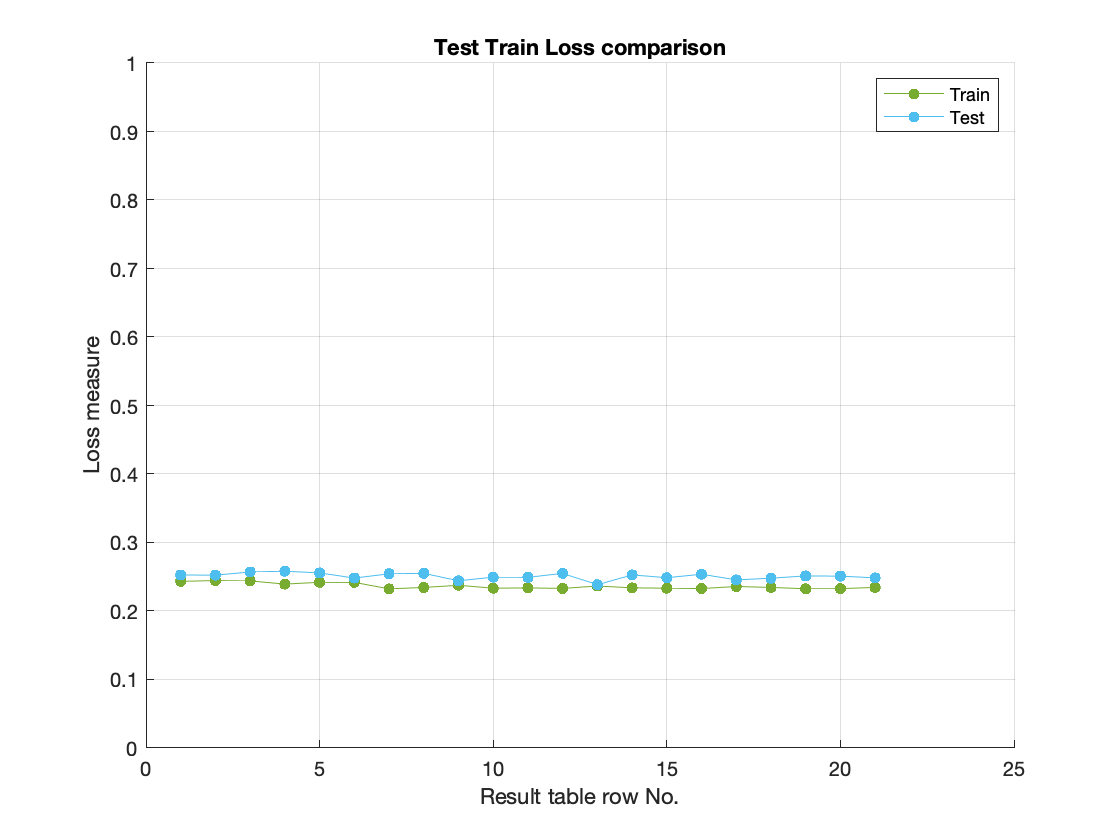

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

disp(results.resultsTable);

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}        {'normal'}      0.2           2                 2               0.24

#### Epanechnikov Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalEpanechnikovSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesEpanechikovSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 2966.8200

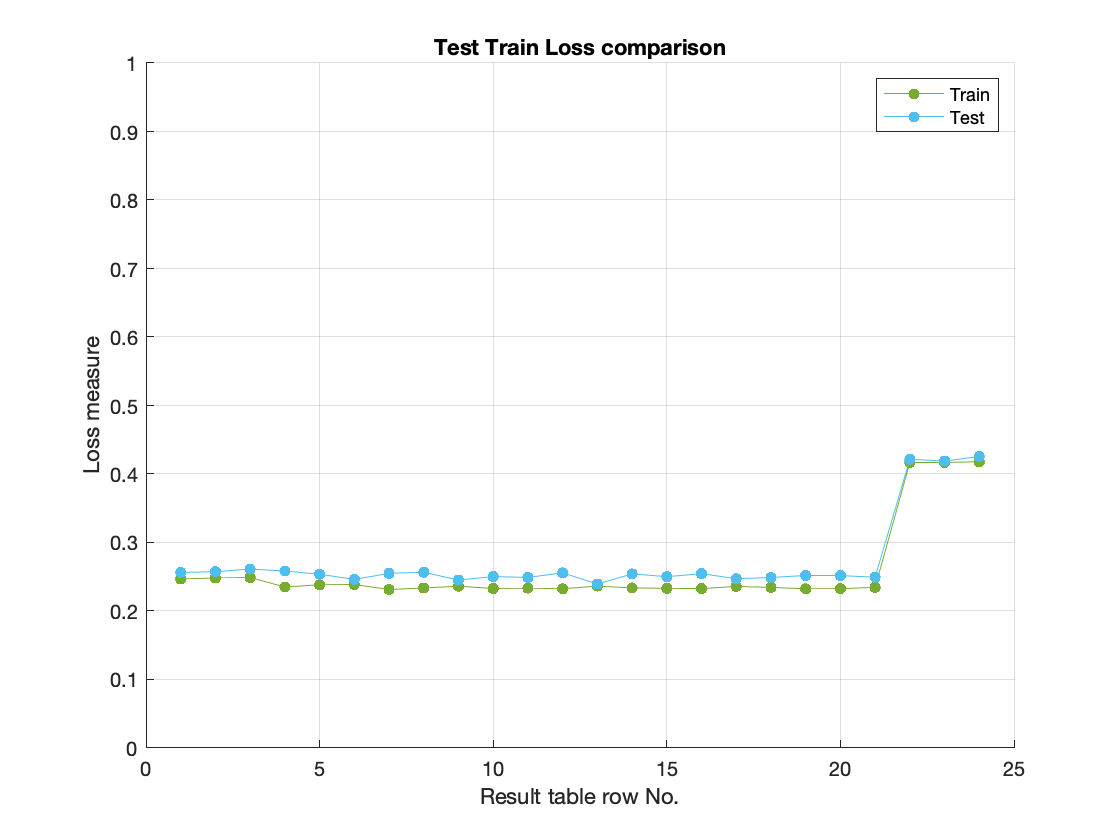

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

disp(results.resultsTable);

    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'epanechnikov'}     0.2           2                 2       

#### Box Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalBoxSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesBoxSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 2576.3200

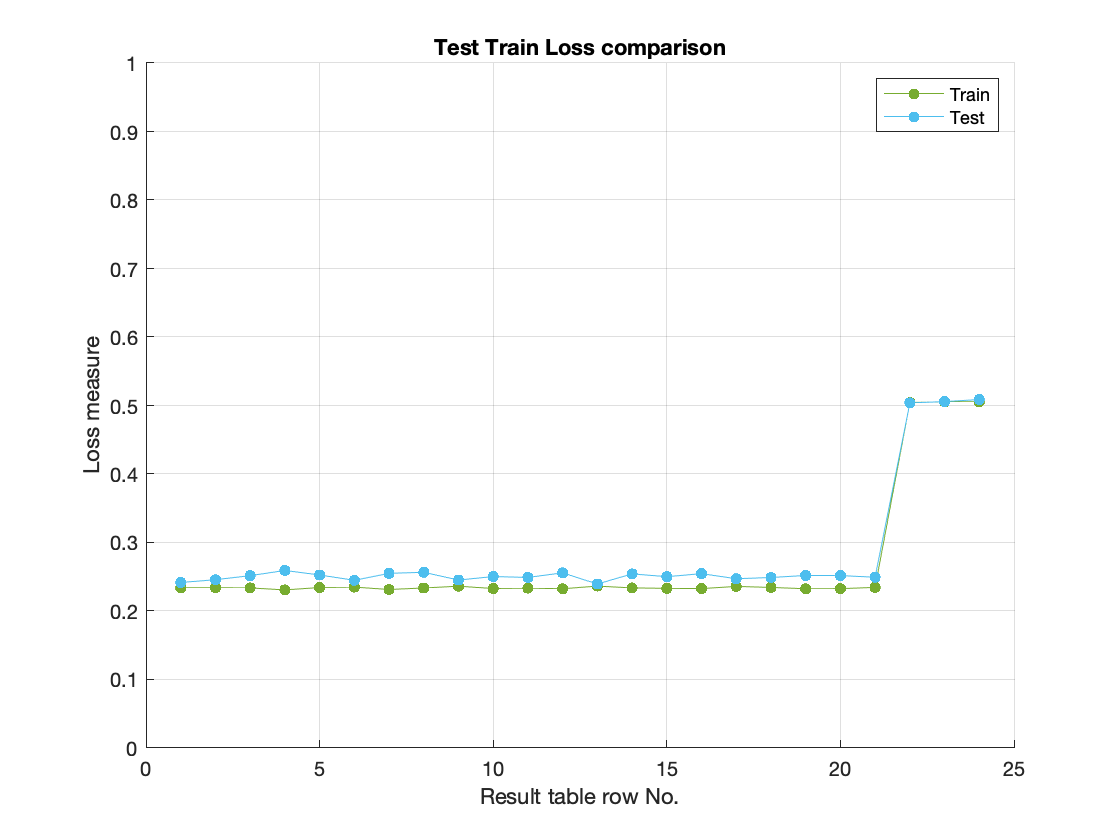

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

disp(results.resultsTable);

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}         {'box'}        0.2           2                 2                0.2

### References

[1] [Multi-Class Metrics Made Simple, Part I: Precision and Recall | by Boaz Shmueli | Towards Data Science](https://towardsdatascience.com/multi-class-metrics-made-simple-part-i-precision-and-recall-9250280bddc2)

[2] [Multi-Class Metrics Made Simple, Part II: the F1-score | by Boaz Shmueli | Towards Data Science](https://towardsdatascience.com/multi-class-metrics-made-simple-part-ii-the-f1-score-ebe8b2c2ca1)

[3] Train multiclass naive Bayes model, fitcnb. MATLAB documentation. [https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html](https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html)